#### **Topological Density and Magnetization Orientation on Magnetic Thin Film:**

The following script can be used to analyze data from a skyrmion simulation. The data has four layers that can be selected below and include three spatial coordinates and three magnetization vector components. 

Enter the desired file name as well as the layer from that file below:




%imports data from desired file

Filename = "Mx_6860.txt";

data = importdata(Filename);

dlayer = "Layer 3";




Select the desired magnetization orientation below such that the vector component magnitude is plotted in the X-Y plane:

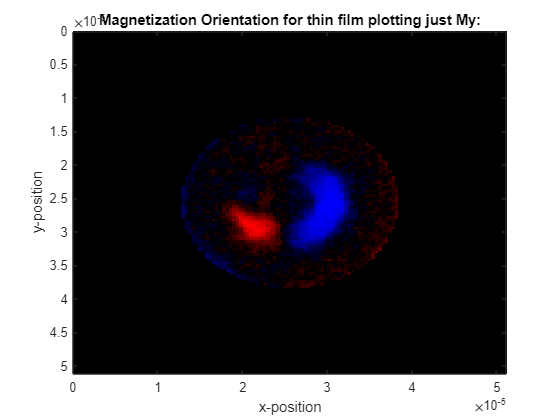

%following code depends on size of file. Assuming that the data structure
%is a 128x128 grid with four layers:


if dlayer=="Layer 1"
    layerdata = data(1:16384,:);

elseif dlayer == "Layer 2"
    layerdata = data(16385:32768,:);

elseif dlayer == "Layer 3"
    layerdata = data(32769:49152,:);

elseif dlayer == "Layer 4"
    layerdata = data(49153:65536,:);
end

%splits data into components for easier comprehension

X = layerdata(:,1); Y = layerdata(:,2); Z = layerdata(:,3);
Mx = layerdata(:,4); My = layerdata(:,5); Mz = layerdata(:,6);

%plottable matrices for the above variables:

Mxplot = reshape(Mx,128,128); Myplot = reshape(My,128,128); Mzplot = reshape(Mz,128,128);
Xplot = reshape(X,128,128); Yplot = reshape(Y,128,128); Zplot = reshape(Z,128,128);


%selectable plot choice:
plot1 = "My";


load('diverging.mat');

if plot1 == "Mz"
    imagesc(X,Y,Mzplot)
    colormap(diverging)
    title("Magnetization Orientation for thin film plotting just Mz:")
    xlabel("x-position")
    ylabel("y-position")
elseif plot1 == "Mx"
    imagesc(X,Y,Mxplot)
    colormap(diverging)
    title("Magnetization Orientation for thin film plotting just Mx:")
    xlabel("x-position")
    ylabel("y-position")
elseif plot1 == "My"
    imagesc(X,Y,Myplot)
    colormap(diverging)
    title("Magnetization Orientation for thin film plotting just My:")
    xlabel("x-position")
    ylabel("y-position")

end



%now wish to add arrow vectors to the above plots by averaging the vector
%components over specific matrix regions


%acting on the matrix we can do this using a 2d-convolution but will return
%a matrix that is too large

windowmatrix = ones(5,5)/5^2; %window size can be adjusted accordingly

convMx = conv2(Mxplot,windowmatrix,'same');
convMy = conv2(Myplot, windowmatrix, 'same');
convMz = conv2(Mzplot,windowmatrix,'same');


%Using the above we now want to shrink the matrix to the desired number of
%quiver arrows;


shrinkfactor = 8;  % must be multiple of 4

buffer = convMx(:,1:shrinkfactor:end) ;
Mx_reduced = buffer(1:shrinkfactor:end,:) ;

buffer = convMy(:,1:shrinkfactor:end) ;
My_reduced = buffer(1:shrinkfactor:end,:) ;

buffer = convMz(:,1:shrinkfactor:end) ;
Mz_reduced = buffer(1:shrinkfactor:end,:) ;



%now need plottable x and y vectors with the same dimension as the above
%reduced magnetization matrices:

X_reduced = X(1:shrinkfactor:end,:);
Y_reduced = Y(1:shrinkfactor:end,:);
Z_reduced = Z(1:shrinkfactor:end,:);

X_reducedplot = X_reduced(1:128/shrinkfactor);
Y_reducedplot=X_reducedplot;
Z_reducedplot=X_reducedplot;



Using a convolution, local averages of the vector components were found. Below, the components in X and Y are overlayed over the desired magnetization:

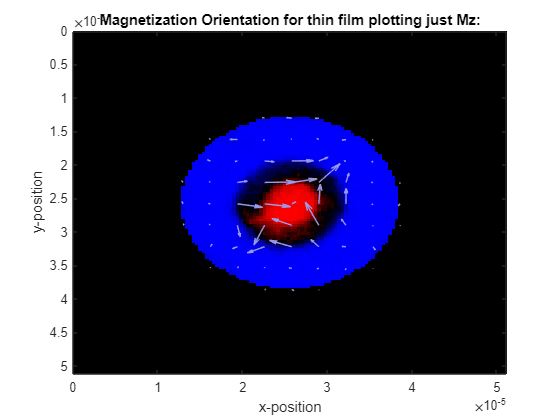

%selectable plot choice:
plot2 = "Mz";


if plot2 == "Mz"
    imagesc(X,Y,Mzplot)
    hold on
    q1 = quiver(X_reducedplot, Y_reducedplot, Mx_reduced,My_reduced);
    q1.Color = '[0.6,0.6,0.9]';
    hold off
    colormap(diverging)
    title("Magnetization Orientation for thin film plotting just Mz:")
    xlabel("x-position")
    ylabel("y-position")
elseif plot2 == "Mx"
    imagesc(X,Y,Mxplot)
    hold on
    q1 = quiver(X_reducedplot, Y_reducedplot, Mx_reduced,My_reduced);
    q1.Color = '[0.6,0.6,0.9]';
    hold off
    colormap(diverging)
    title("Magnetization Orientation for thin film plotting just Mx:")
    xlabel("x-position")
    ylabel("y-position")
elseif plot2 == "My"
    imagesc(X,Y,Myplot)
    hold on
    q1 = quiver(X_reducedplot, Y_reducedplot, Mx_reduced,My_reduced);
    q1.Color = '[0.6,0.6,0.9]';
    hold off
    colormap(diverging)
    title("Magnetization Orientation for thin film plotting just My:")
    xlabel("x-position")
    ylabel("y-position")
end

A 3 dimensional visualisation of the vector field in the chosen layer is below:

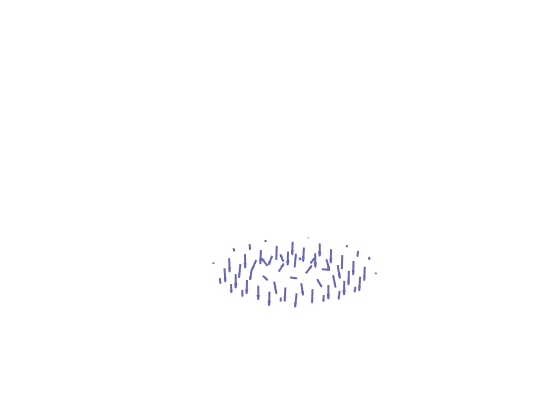


%quick and dirty quiver plot to check if things are in line, will try a
%cone plot below:

%cmap:
%cmap = colormap(hsv(360));

X3= meshgrid(X_reducedplot, X_reducedplot);

%{
distances = X_reducedplot;
numPoints = numel(X_reducedplot)
markerSizes = 200 * distances;
indexes = round(rescale(markerSizes, 1, numPoints));
colors = jet(numPoints);
colors = colors(indexes,:);
%}

q2 = quiver3(X3,Mx_reduced,My_reduced,Mz_reduced, 0.3, 'linewidth', 1.5, 'Color',[0.4,0.4,0.7],"Alignment","tail");%"linewidth", 0.8,"AutoScale","on","AutoScaleFactor",0.1);
zlim([-0.5,5])
view([-35.30 32.00])
lighting flat
camlight 
axis off




zerodarkthirty = zeros(128,128,127);


zeroX = cat(3, Mxplot, zerodarkthirty);
zeroY = cat(3, Myplot, zerodarkthirty);
zeroZ = cat(3, Mzplot, zerodarkthirty);


cx = linspace(1e-7,2.55000000000000e-05);

%Mxplot(end, end, 2) = 0; 
%Myplot(end,end,2) = 0;
%Mzplot(end,end,2) = 0;

%coneplot(zeroX,zeroY,zeroZ,Xplot,Yplot,Zplot)




Finally, the goal of this script is to find both the topological density and skyrmion number for the given data. For a two dimensional layer of magnetization vectors, the skyrmion number is given by the following equation:

$\mathcal{N} = \frac{1}{4\pi} \int n(x,y) dx dy$            (1)                                                                           

Where n is the topological density profile of the given film. We can determine the topological density over x and y with just the mganetization using the following:

$n(x,y) = \bf{m} \cdot ( \partial_x \bf{m} \times \partial _y \bf{m})$         (2)

The magnetization vectors above are normalized to the saturation magnetization $M_s$ . Below is the plotted topological density for the chosen layer.

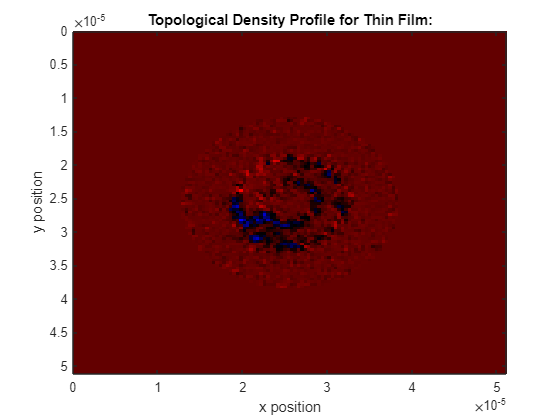




%Using equation 2 we can find the topological density for the data. We
%first need to find the partial derivatives of all three vector field
%components with respect to both x and y:

%Usable data here is the grids for Mx,My,Mz from earlier:

[Mx_dx, Mx_dy] = gradient(Mxplot);
[My_dx, My_dy] = gradient(Myplot);
[Mz_dx, Mz_dy] = gradient(Mzplot);

%vector components:
Mx_dx_vec = reshape(Mx_dx,16384,1); Mx_dy_vec = reshape(Mx_dy,16384,1); My_dx_vec = reshape(My_dx,16384,1);
My_dy_vec = reshape(My_dy,16384,1); Mz_dx_vec = reshape(Mz_dx,16384,1); Mz_dy_vec = reshape(Mz_dy,16384,1);


%individual full vector components:

total_dx = [Mx_dx_vec My_dx_vec Mz_dx_vec];
total_dy = [Mx_dy_vec My_dy_vec Mz_dy_vec];

total_magnetization = [Mx My Mz];


%can now take the term by term cross product of the above column vectors:

crossterm = cross(total_dx,total_dy);

%and finally the topological density is found by taking the term by term
%dot product with the above cross product term:


topdens = dot(total_magnetization', crossterm')';
%load('topdense.mat')
%reshape to plot in the x,y plane:

topological = reshape(topdens, 128,128);


imagesc(X,Y,topological)
%colormap(topdense)
title("Topological Density Profile for Thin Film:")
xlabel("x position")
ylabel("y position")

The same plot with a bilinear interpolation scheme such that the initial bin width resolution of the data is hidden:

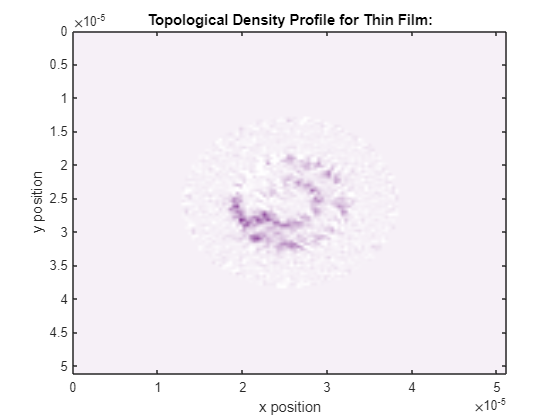

load('topdense2.mat')
imagesc(X,Y,topological, "Interpolation", "bilinear")
colormap(topdense2)
title("Topological Density Profile for Thin Film:")
xlabel("x position")
ylabel("y position")

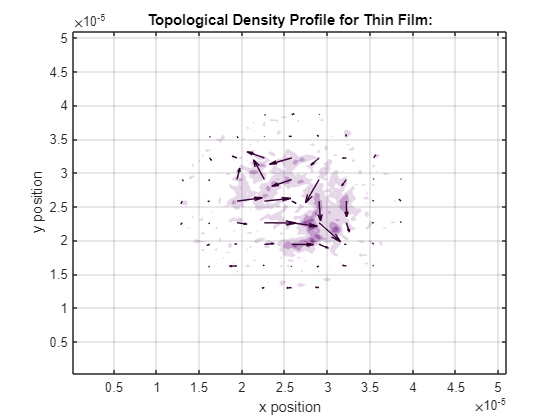

%grid on


contourf(Xplot,Yplot,topological, 5, "LineColor", 'none')
colormap(topdense2)
title("Topological Density Profile for Thin Film:")
xlabel("x position")
ylabel("y position")
hold on
q4 = quiver(X_reducedplot, Y_reducedplot, Mx_reduced,My_reduced);
q4.Color = '[0.2,0,0.2]';
hold off
Xtick = linspace(0,2.55e-5,10);
grid on

Using equation 1, we can then find the skyrmion number for the system. The expected value should be very close to an integer or zero. For an antiskyrmion, the value will be $\sim -1$.


%now want to integrate using equation one to find the skyrmion number:

partial_int = trapz(topological);

full_integral = trapz(partial_int) / (4*pi);
fprintf("The skyrmion number for this configuration is %.4f", full_integral)

The skyrmion number for this configuration is -0.9543





[TopD, sky] = topdensefunc(X,Y,Z,Mx,My,Mz);

sky

sky = -0.9543

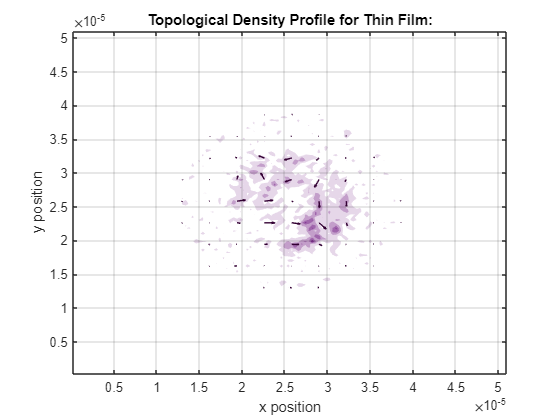


contourf(Xplot,Yplot,TopD, 5, "LineColor", 'none')
colormap(topdense2)
title("Topological Density Profile for Thin Film:")
xlabel("x position")
ylabel("y position")
hold on
q3 = quiver(X_reducedplot, Y_reducedplot, Mx_reduced,My_reduced,0.3);
q3.Color = '[0.2,0,0.2]';
hold off
Xtick = linspace(0,2.55e-5,10);
grid on

%view(3)

Now to visualize 3D vectors:

%Now want to visualize 3D vector data using cone plot:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%splits data into components for easier comprehension

X2 = data(:,1); Y2 = data(:,2); Z2 = data(:,3);
Mx2 = data(:,4); My2 = data(:,5); Mz2 = data(:,6);

%plottable matrices for the above variables:
X3 = reshape(X2, 128,128,4); Y3 = reshape(Y2, 128,128,4); Z3 = reshape(Z2, 128,128,4);

Error using reshape
Number of elements must not
change. Use [] as one of the
size inputs to automatically
calculate the appropriate
size for that dimension.

Mx3 = reshape(Mx2, 128,128,4); My3 = reshape(My2, 128,128,4); Mz3 = reshape(Mz2, 128,128,4);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
xmin = min(X2(:));
xmax = max(X2(:));
ymin = min(Y2(:));
ymax = max(Y2(:));
zmin = min(Z2(:));
zmax = max(Z2(:));

xrange = linspace(xmin, xmax, 128);
yrange = linspace(ymin, ymax, 128);
zrange = linspace(zmin, zmax, 4);



cxrange = linspace(xmin, xmax, 12);
cyrange = linspace(ymin, ymax, 12);
czrange = linspace(2e-7, 5e-7, 2);

[cx,cy,cz ] = meshgrid(cxrange,cyrange,czrange);

[X3,Y3,Z3] = meshgrid(xrange,yrange,zrange);

mags = sqrt(Mx3.^2 + My3.^2 + Mz3.^2);
load('coneplot1.mat')
load('coneplot2.mat')
load('coneplot3.mat')



%attempt to add a contour plot beneath of the topological density:


copytopdense = repmat(TopD, [1 1 4]);


figure(6);


h=coneplot( X3,Y3,(Z3),Mx3,My3,Mz3, cx,cy,cz,8,Mz3, "cubic");
view(3)
colormap(coneplot2)
set(h, 'EdgeColor', 'none');
camlight;
lighting gouraud;
%axis off;
pbaspect([8 8 1])
shading interp
axis off
lightangle(45,45)
V = copytopdense;
xslice = [];
yslice = [];
zslice = [0,0,0];
cs  = contourslice(X3,Y3,Z3, V, xslice,yslice,zslice,5,"cubic");
shading interp







figure(2);
ax1 = subplot(2,1,1);
h=coneplot(ax1, X3,Y3,(Z3),Mx3,My3,Mz3, cx,cy,cz,10,-Mz3, "cubic");
view(3)
colormap(ax1,coneplot2)
set(h, 'EdgeColor', 'none');
plotObjs=h;
camlight;
lighting gouraud;
%axis off;
pbaspect([8 8 1])
shading interp
axis off
lightangle(45,45)
ax2 = subplot(2,1,2);
axis off;
V = copytopdense;
xslice = [];
yslice = [];
zslice = [0,0,1e-7];
cs = contourslice(ax2,X3,Y3,Z3, V, xslice,yslice,zslice,8,"cubic");
colormap(ax2, coneplot3)
subplot(2,1,2)
view([-34.50 90.00])


axis off;


%h.FaceLighting = 'gouraud';
%h.AmbientStrength = 0.5;
%h.DiffuseStrength = 0.9;
%h.SpecularStrength = 0.4;
%h.SpecularExponent = 25;
%h.BackFaceLighting = 'unlit';

%camproj perspective



figure(4); 
ax1 = subplot(2,1,2);
h=coneplot(ax1, X3,Y3,(Z3),Mx3,My3,Mz3, cx,cy,cz,15,-Mz3, "cubic");
colormap(coneplot1)
set(h, 'EdgeColor', 'none');
view(3)
camlight;
lighting gouraud;
axis off;
pbaspect([6 6 1])
colormap(coneplot2)
shading interp
lightangle(45,45)

ax2 = subplot(2,1,1);
czrange = linspace(6e-7, 8e-7, 4);
[cx,cy,cz ] = meshgrid(cxrange,cyrange,czrange);
h2=coneplot(ax2, X3,Y3,(Z3),Mx3,My3,Mz3, cx,cy,cz,15,-Mz3, "cubic");
colormap(coneplot1)
set(h2, 'EdgeColor', 'none');
view(3)
camlight;
lighting gouraud;
axis off;
pbaspect([8 8 1])
colormap(coneplot2)
shading interp
lightangle(45,45)